# SIM的仿真算法实现

## 1. 生成正弦的照明图案

照明结构光的表达式如下：

时域表示：$I_{\theta,\phi}(\mathbf{r})=I_0[\frac{1}{2}-\frac{m}{2}cos(2\pi\mathbf{p_\theta}\cdot\mathbf{r}+\phi)  ]$

频域表示：$\tilde{I}_{\theta,\phi}(\mathbf{k})=I_0[\frac{1}{2}-\frac{m}{2} 
 \cdot \frac{1}{2}    (\delta(\mathbf{k}-\mathbf{p_\theta})e^{-i\phi}+\delta(\mathbf{k}+\mathbf{p_\theta})e^{i\phi}) ]$

其中$\theta $代表照明结构光的方向，在本仿真中我采用了三个方向的结构光：$\theta_1=0^o;\theta_2=60^o;\theta_3=120^oor-60^o;$

$\phi$代表照明结构光的相位 ，在本仿真中我采用了三个相位的结构光：$\phi_1=0^o;\phi_2=90^o;\phi_3=180^o;$

$I_0$代表照明结构光的峰值强度，在本仿真中我采用了$I_0=1$；

m代表调制系数，在本仿真中我采用了m=1；

$\mathbf{p}_\theta$代表结构光调制荧光样本后使其产生的频移量

### 1.1 生成三个相位的照明光

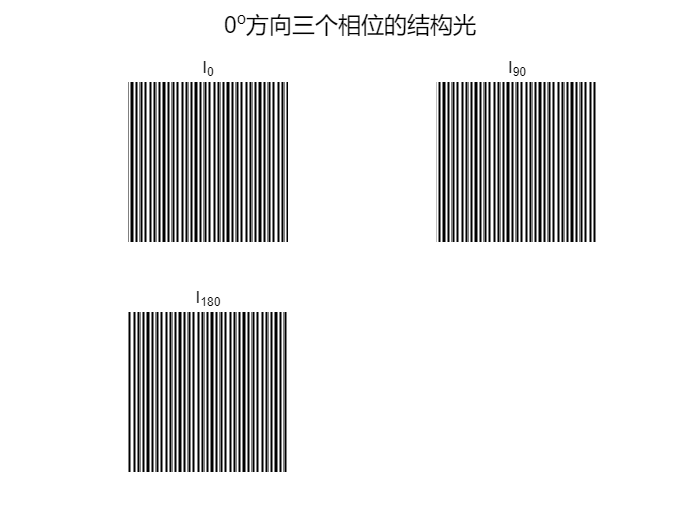

row=500;
col=500;
%生成0度相位结构光
I_0=zeros(row,col);
for i=1:4
    switch i
        case 1
            I_0(:,i:4:col)=1;
        case 2
            I_0(:,i:4:col)=0.5;
        case 3
            I_0(:,i:4:col)=0;
        otherwise
            I_0(:,i:4:col)=0.5;
    end
end
figure;subplot(2,2,1);sgtitle("0^o方向三个相位的结构光");
imshow(I_0,[]);title("I_{0}")
%生成90度相位结构光
I_90=[I_0(:,2:end),I_0(:,1)];
subplot(2,2,2);
imshow(I_90,[]);title("I_{90}")
%生成180度相位结构光
I_180=[I_0(:,3:end),I_0(:,1:2)];
subplot(2,2,3);
imshow(I_180,[]);title("I_{180}")

### 1.1 生成三个方向的照明光

三个方向的结构光：$\theta_1=0^o;\theta_2=60^o;\theta_3=120^oor-60^o;$

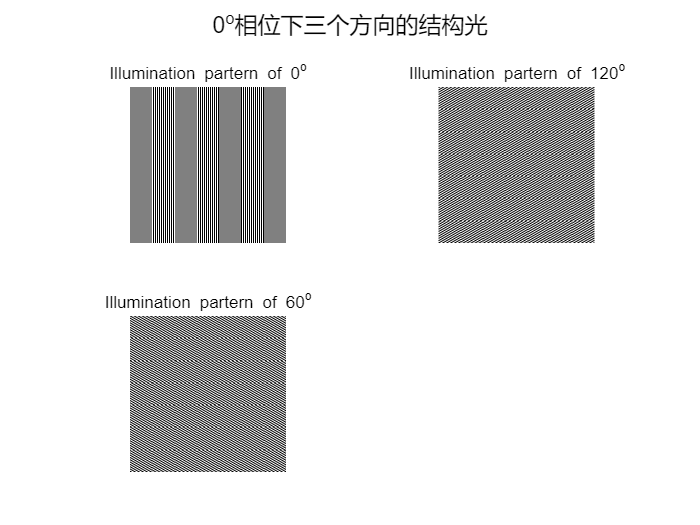

%零相位下的三个方向
I_0_60=imrotate(I_0,60,"bilinear","crop");
I_0_120=imrotate(I_0,120,"bilinear","crop");
%对图像进行取块
I_0_0=I_0(250-152:250+152,250-152:250+152);
I_0_60=I_0_60(250-152:250+152,250-152:250+152);
I_0_120=I_0_120(250-152:250+152,250-152:250+152);
figure;sgtitle("0^o相位下三个方向的结构光");
subplot(2,2,1);imshow(I_0_0);
title("Illumination partern of 0^o");
subplot(2,2,2);imshow(I_0_120);
title("Illumination partern of 120^o");
subplot(2,2,3);imshow(I_0_60);
title("Illumination partern of 60^o");

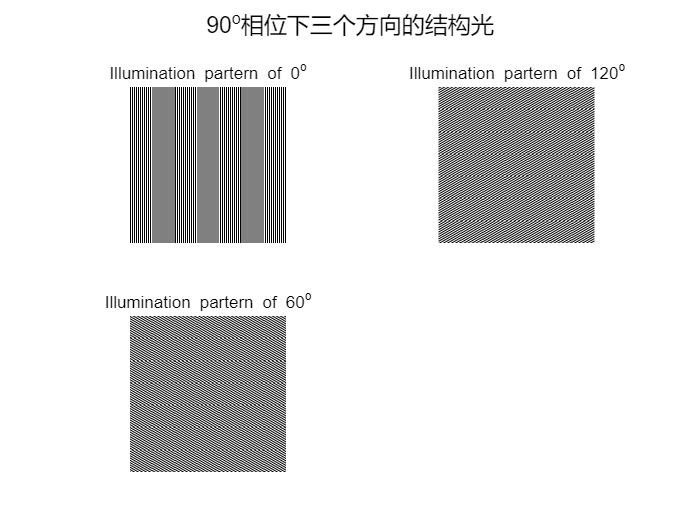


%九十度相位下的三个方向
I_90_60=imrotate(I_90,60,"bilinear","crop");
I_90_120=imrotate(I_90,120,"bilinear","crop");
%对图像进行取块
I_90_0=I_90(250-152:250+152,250-152:250+152);
I_90_60=I_90_60(250-152:250+152,250-152:250+152);
I_90_120=I_90_120(250-152:250+152,250-152:250+152);
figure;sgtitle("90^o相位下三个方向的结构光");
subplot(2,2,1);imshow(I_90_0);
title("Illumination partern of 0^o");
subplot(2,2,2);imshow(I_90_120);
title("Illumination partern of 120^o");
subplot(2,2,3);imshow(I_90_60);
title("Illumination partern of 60^o");

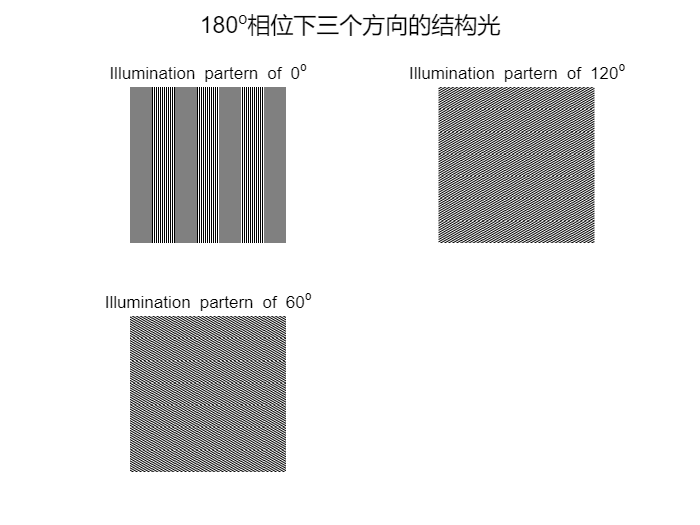


%一百八十度相位下的三个方向
I_180_60=imrotate(I_180,60,"bilinear","crop");
I_180_120=imrotate(I_180,120,"bilinear","crop");
%对图像进行取块
I_180_0=I_180(250-152:250+152,250-152:250+152);
I_180_60=I_180_60(250-152:250+152,250-152:250+152);
I_180_120=I_180_120(250-152:250+152,250-152:250+152);
figure;sgtitle("180^o相位下三个方向的结构光");
subplot(2,2,1);imshow(I_180_0);
title("Illumination partern of 0^o");
subplot(2,2,2);imshow(I_180_120);
title("Illumination partern of 120^o");
subplot(2,2,3);imshow(I_180_60);
title("Illumination partern of 60^o");

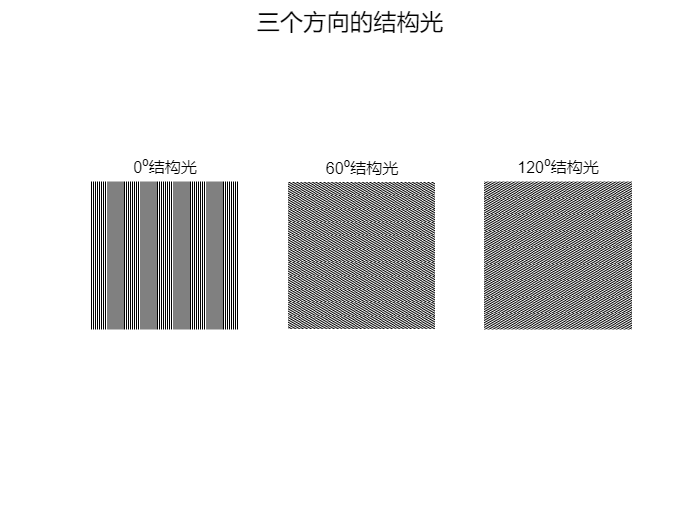

figure;sgtitle("三个方向的结构光");
subplot(1,3,1);imshow(I_0_0);title("0^o结构光");
subplot(1,3,2);imshow(I_0_60);title("60^o结构光");
subplot(1,3,3);imshow(I_0_120);title("120^o结构光");

## 2. 读取图像，并生成经过物镜低通滤波后的图像

### 2.1 读取图像，并转换到频域表示

%读取图像，并将其转换为灰度图
img=imread('下载.jfif');
in_f=rgb2gray(img);    %对于RGB图像必须做的一步，也可以用im2double函数
figure;
subplot(2,3,1);imshow(in_f);title('原图');

%输出图像格式信息
whos in_f

  Name        Size              Bytes  Class    Attributes

  in_f      342x305            104310  uint8              



%将图像调整为正方形305*305，使后续频谱图中X,Y方向的频率间隔相同
f=in_f(19:342-19,:);

%生成频谱图
F=fft2(f);          %傅里叶变换
% F1=log(abs(F)+1);   %取模并进行缩放
% subplot(2,2,2);imshow(F1,[]);title('傅里叶变换频谱图');
Fs=fftshift(F);      %将频谱图中零频率成分移动至频谱图中心
S=log(abs(Fs)+1);    %取模并进行缩放
subplot(2,3,2);imshow(S,[]);title('原图的频谱图');
%逆傅里叶变换
% fr=real(ifft2(ifftshift(Fs)));  %频率域反变换到空间域，并取实部
% ret=im2uint8(mat2gray(fr));    %更改图像类型
% subplot(2,2,3);imshow(ret),title('逆傅里叶变换');

### 2.2 生成物镜传递函数的掩膜版

为了简化仿真，我将光学系统的传递函数$\tilde{H}(\mathbf{k})$定义为在以频谱图中心为原点，直径为频谱图一半的圆之中的频率成分可以无损通过，之外的频率成分则被完全滤除的OTF。


$$\tilde{H}(\mathbf{k})
=
circ(\frac{|\mathbf{k}|}{D/2})$$


宽场荧光显微镜对物体所成的像：


$$D_{WF}(\mathbf{r})=S(\mathbf{r})*H(\mathbf{r})$$


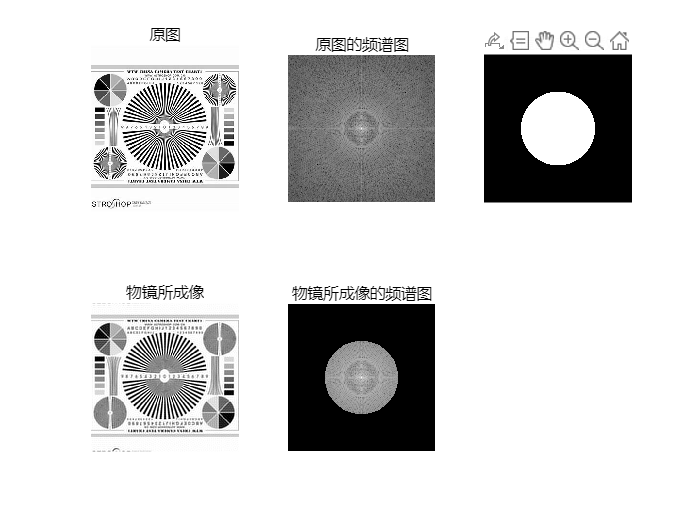

% 定义用于找二维矩阵中最大值索引的函数，帮助我们找到频谱图的中心
% 即频谱中的零频点。
function [row_ind,col_ind]=Find_max_index(A)
    [col_max_value, col_max_index] = max(A);
    [all_max_value,all_max_index]=max(col_max_value);
    row_ind=col_max_index(all_max_index);
    col_ind=all_max_index;
end

[row_max,col_max]=Find_max_index(S);
mask=circles2mask([col_max,row_max],floor(col_max/2),size(S));
subplot(2,3,3);imshow(mask);title("物镜的传递函数");
masked_img = Fs.* mask; % 使用位运算符将掩膜和图像对应部分相乘
subplot(2,3,5);imshow(log(abs(masked_img)+1),[]);
title("物镜所成像的频谱图");

%生成经过物镜低通滤波后所成像
lowpass_f=real(ifft2(ifftshift(masked_img/255)));
subplot(2,3,4);imshow(lowpass_f);
title("物镜所成像");

## 3. 生成被结构光照明并经过物镜低通滤波后的时域和频域的图像

### 3.1被结构光照明的时域图像


$$D_{\theta,\phi}(\mathbf{r})=[S(\mathbf{r})I_{\theta,\phi}(\mathbf{r})]*H(\mathbf{r})$$


其中：$D_{\theta,\phi}(\mathbf{r})$：通过光学系统观察到的被结构光照明的图像；$S(\mathbf{r})$：样本中的荧光分布；$H(\mathbf{r})$：光学系统的点扩展函数。

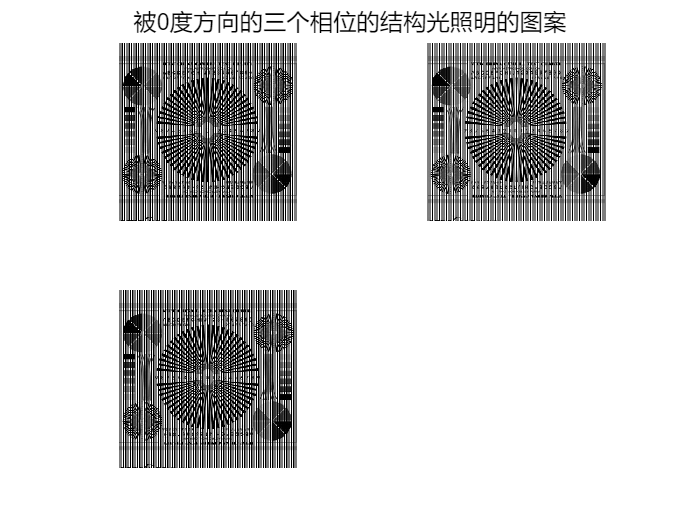

%0度方向的三个相位
SI_0_0=immultiply(double(f)/255,I_0_0);
SI_90_0=immultiply(double(f)/255,I_90_0);
SI_180_0=immultiply(double(f)/255,I_180_0);
figure;sgtitle("被0度方向的三个相位的结构光照明的图案");
subplot(2,2,1);imshow(SI_0_0);
subplot(2,2,2);imshow(SI_90_0);
subplot(2,2,3);imshow(SI_180_0);

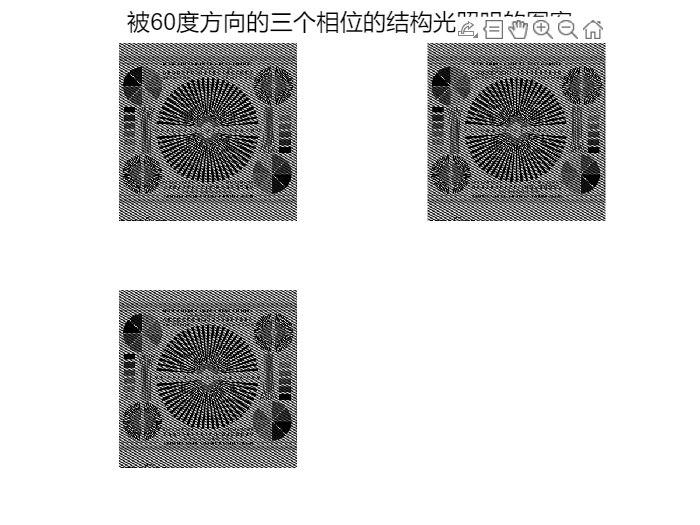


%60度方向的三个相位
SI_0_60=immultiply(double(f)/255,I_0_60);
SI_90_60=immultiply(double(f)/255,I_90_60);
SI_180_60=immultiply(double(f)/255,I_180_60);
figure;sgtitle("被60度方向的三个相位的结构光照明的图案");
subplot(2,2,1);imshow(SI_0_60);
subplot(2,2,2);imshow(SI_90_60);
subplot(2,2,3);imshow(SI_180_60);

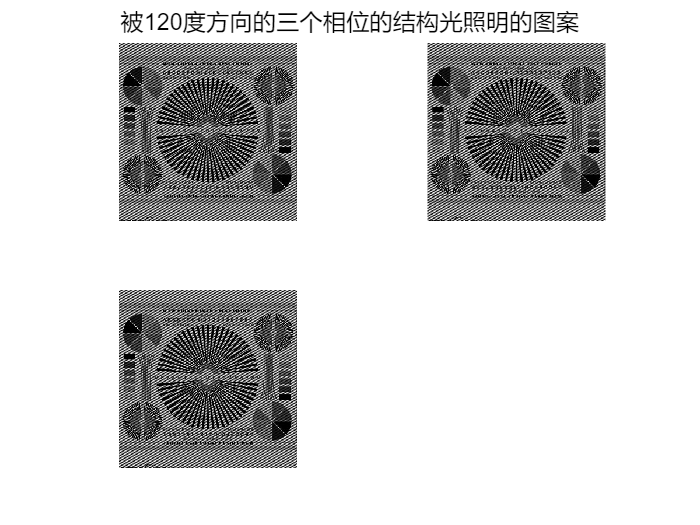


%120度方向的三个相位
SI_0_120=immultiply(double(f)/255,I_0_120);
SI_90_120=immultiply(double(f)/255,I_90_120);
SI_180_120=immultiply(double(f)/255,I_180_120);
figure;sgtitle("被120度方向的三个相位的结构光照明的图案");
subplot(2,2,1);imshow(SI_0_120);
subplot(2,2,2);imshow(SI_90_120);
subplot(2,2,3);imshow(SI_180_120);

### 3.1被结构光照明图像的频谱图


$$\tilde{D}_{\theta,\phi}({\mathbf{k})}=[\tilde{I}_{\theta,\phi}(\mathbf{k})*\tilde{S}(\mathbf{k})]\cdot \tilde{H}(\mathbf{k})
\\
\  \ \ \ \ \ =\frac{I_0}{2}[\tilde{S}(\mathbf{k})  -  \frac{m}{2}\tilde{S}(\mathbf{k}-\mathbf{p_\theta})e^{-i\theta}  -    \frac{m}{2}\tilde{S}(\mathbf{k}+\mathbf{p_\theta})e^{i\theta}]  \cdot  \tilde{H}(\mathbf{k})$$


%计算结构光照明的物体所成像的频谱图,
%sig: 1:取模进行缩放； 0：保持原样
function masked_S=microscopy_spec(SI,sig)
    F_SI=fft2(SI);          %傅里叶变换
    Fs_SI=fftshift(F_SI);      %将频谱图中零频率成分移动至频谱图中心
    if sig==1
        S=log(abs(Fs_SI)+1);    %取模并进行缩放
    else
        S=Fs_SI;
    end
    [r,c]=Find_max_index(S);
    mask=circles2mask([c,r],c/2,size(S));
    masked_S = S.* mask; % 使用位运算符将掩膜和图像对应部分相乘
end

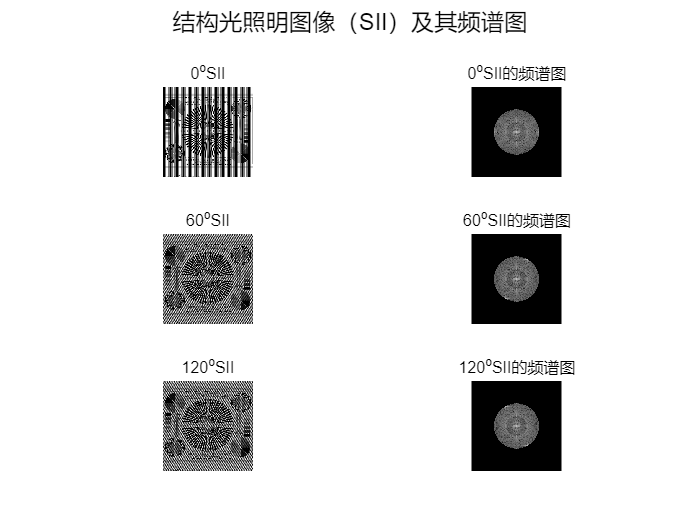

%0度方向
masked_S_0_0=microscopy_spec(SI_0_0,0);
masked_S_90_0 = microscopy_spec(SI_90_0,0);
masked_S_180_0 = microscopy_spec(SI_180_0,0);
figure;sgtitle("结构光照明图像（SII）及其频谱图")
subplot(3,2,1);imshow(SI_0_0);title("0^oSII")
subplot(3,2,2);imshow(log(abs(masked_S_0_0)+1),[]);title("0^oSII的频谱图")

%60度方向
masked_S_0_60 = microscopy_spec(SI_0_60,0);
masked_S_90_60 = microscopy_spec(SI_90_60,0);
masked_S_180_60 = microscopy_spec(SI_180_60,0);

subplot(3,2,3);imshow(SI_0_60);title("60^oSII")
subplot(3,2,4);imshow(log(abs(masked_S_0_60)+1),[]);title("60^oSII的频谱图")

%120度方向
masked_S_0_120 = microscopy_spec(SI_0_120,0);
masked_S_90_120 = microscopy_spec(SI_90_120,0);
masked_S_180_120 = microscopy_spec(SI_180_120,0);

subplot(3,2,5);imshow(SI_0_120);title("120^oSII");
subplot(3,2,6);imshow(log(abs(masked_S_0_120)+1),[]);title("120^oSII的频谱图")

## 4. SIM 图像重建

### 4.1 理论

将三个相位对应的方程：


$$\tilde{D}_{\theta,\phi}({\mathbf{k})}
=
\frac{I_0}{2}[\tilde{S}(\mathbf{k})  -  \frac{m}{2}\tilde{S}(\mathbf{k}-\mathbf{p_\theta})e^{-i\theta}  -    \frac{m}{2}\tilde{S}(\mathbf{k}+\mathbf{p_\theta})e^{i\theta}]  \cdot  \tilde{H}(\mathbf{k})$$


以矩阵的形式表示为：


$$ \left[ \begin{array}{c}\tilde{D}_{\theta,\phi _{1}}({\mathbf {k}}) \\ \tilde{D}_{\theta,\phi _{2}}({\mathbf {k}}) \\ \tilde{D}_{\theta,\phi _{3}}({\mathbf {k}}) \end{array} \right] =
 \frac{I_{o}}{2}

\left[ \begin{array}{ccc}1 & -\frac{m}{2} & -\frac{m}{2} \\ 1 & -\frac{m}{2}e^{-i\phi _{2}} & -\frac{m}{2}e^{+i\phi _{2}} \\ 1 & -\frac{m}{2}e^{-i\phi _{3}} & -\frac{m}{2}e^{+i\phi_{3}} \end{array} \right]

\left[ \begin{array}{c}\tilde{S}({\mathbf {k}})\tilde{H}({\mathbf {k}}) \\ \tilde{S}({\mathbf {k}}-{\mathbf {p}}_{\theta })\tilde{H}({\mathbf {k}}) \\ \tilde{S}({\mathbf {k}}+{\mathbf {p}}_{\theta })\tilde{H}({\mathbf {k}}) \end{array} \right] $$



$$ \text{make}\quad{\mathbf {M}}=\left[ \begin{array}{ccc}1 & -\frac{m}{2} &-\frac{m}{2} \\ 1& -\frac{m}{2}e^{-i\phi ^{\prime }_{2}} & -\frac{m}{2}e^{+i\phi ^{\prime }_{2}} \\ 1 & -\frac{m}{2}e^{-i\phi ^{\prime }_{3}} & -\frac{m}{2}e^{+i\phi ^{\prime }_{3}} \end{array} \right]$$


所以我们可以通过如下方程来求解出被结构光照明图像的频谱图中的频移组分：


$$\left[ \begin{array}{c}\tilde{S}({\mathbf {k}})\tilde{H}({\mathbf {k}}) \\ \tilde{S}({\mathbf {k}}-{\mathbf {p}}_{\theta })\tilde{H}({\mathbf {k}}) \\ \tilde{S}({\mathbf {k}}+{\mathbf {p}}_{\theta })\tilde{H}({\mathbf {k}}) \end{array} \right] =
\frac{2}{I_0}\mathbf{M}^{-1}

 \left[ \begin{array}{c}\tilde{D}_{\theta,\phi _{1}}({\mathbf {k}}) \\ \tilde{D}_{\theta,\phi _{2}}({\mathbf {k}}) \\ \tilde{D}_{\theta,\phi _{3}}({\mathbf {k}}) \end{array} \right]$$


为了表示出等号左边三个分量在仿真代码中是三个相互独立的变量，我们令：


$$\left[ \begin{array}{c}
     \tilde{S}_{M}({\mathbf {k}})
 \\ \tilde{S}_{R}({\mathbf {k}})
 \\ \tilde{S}_{L}({\mathbf {k}})
 \end{array} \right]
=
\left[ \begin{array}{c}\tilde{S}({\mathbf {k}})\tilde{H}({\mathbf {k}}) \\ \tilde{S}({\mathbf {k}}-{\mathbf {p}}_{\theta })\tilde{H}({\mathbf {k}}) \\ \tilde{S}({\mathbf {k}}+{\mathbf {p}}_{\theta })\tilde{H}({\mathbf {k}}) \end{array} \right]$$


其中$ \tilde{S}_{M}({\mathbf {k}})$:未被搬移的频谱组分；  $ \tilde{S}_{L}({\mathbf {k}})$ ：被向左搬移的频谱组分； $ \tilde{S}_{R}({\mathbf {k}})$：背向右搬移的频谱组分。

### 平移

然后我们对三个方向结构光照明的图像的频谱图分别应用上述方法分解出频谱图中的频移成分，再应用以下计算方法将各频移成分频移回原位。


$$ \tilde{S}_{SR}({\mathbf {k}}) 
=
 \tilde{S}_{R}({\mathbf {k}}+{\mathbf {p}}_{\theta }) 
\\
\tilde{S}_{SL}({\mathbf {k}}) 
=
 \tilde{S}_{L}({\mathbf {k}}-{\mathbf {p}}_{\theta }) $$


### 合并

之后我们将从频谱图中分解出来的各个频率组分组合起来，构成完整的在各方向上近似扩展了两倍的频谱图。


$$ \tilde{S}_{SIM,\theta}({\mathbf {k}})
= 
\tilde{S}_{M,\theta}({\mathbf {k}})
\cup
\tilde{S}_{SL,\theta}({\mathbf {k}})
\cup
\tilde{S}_{SR,\theta}({\mathbf {k}})$$



$$ \tilde{S}_{SIM}({\mathbf {k}})
= 
 \tilde{S}_{SIM,\theta_1}({\mathbf {k}})
\cup
 \tilde{S}_{SIM,\theta_2}({\mathbf {k}})
\cup
 \tilde{S}_{SIM,\theta_3}({\mathbf {k}})$$


### 傅里叶逆变换

最后我将组合起来的频谱图进行傅里叶逆变换，最终便重建出了个方向上分辨率近似提升了两倍的图像。


$$S_{SIM}({\mathbf {r}})
=
\mathcal {F}^{-1}\left\lbrace \tilde{S}_{SIM}({\mathbf {k}})\right\rbrace $$


### 4.2 代码实现

构建矩阵$\quad{\mathbf {M}}=\left[ \begin{array}{ccc}1 & -\frac{m}{2} &-\frac{m}{2} \\ 1& -\frac{m}{2}e^{-i\phi ^{\prime }_{2}} & -\frac{m}{2}e^{+i\phi ^{\prime }_{2}} \\ 1 & -\frac{m}{2}e^{-i\phi ^{\prime }_{3}} & -\frac{m}{2}e^{+i\phi ^{\prime }_{3}} \end{array} \right]$

m=1;
M=[1 -m/2 -m/2;
    1 -m/2*exp(-j*pi/2) -m/2*exp(j*pi/2);
    1 -m/2*exp(-j*pi) -m/2*exp(j*pi);];
M_inv=inv(M);

### 1. 0度方向

%分解出中间的频率成分
S_M_0=M_inv(1,1)*masked_S_0_0+M_inv(1,2)*masked_S_90_0+M_inv(1,3)*masked_S_180_0;
figure;sgtitle("0^o方向频谱组分的分解")
subplot(3,3,1);imshow(log(abs(masked_S_0_0)+1)/10);title(' $ \tilde{D}_{\theta=0,\phi}({\mathbf{k})}$', 'interpreter', 'latex');
subplot(3,3,2);imshow(log(abs(S_M_0)+1)/10);title(' $ \tilde{S}_{M}({\mathbf {k}})$', 'interpreter', 'latex');
%分解出左边的频率成分
S_L_0=M_inv(2,1)*masked_S_0_0+M_inv(2,2)*masked_S_90_0+M_inv(2,3)*masked_S_180_0;
subplot(3,3,4); imshow(log(abs(S_L_0)+1)/10); title(' $ \tilde{S}_{L}({\mathbf {k}})$', 'interpreter', 'latex');

### 平移

[row_L_0,col_L_0]=Find_max_index(S_L_0)

row_L_0 = 153

col_L_0 = 77

S_S_L_0=[S_L_0(:,305-75:305),S_L_0(:,1:305-76)];
subplot(3,3,5);
imshow(log(abs(S_S_L_0)+1)/10); title(' $  \tilde{S}_{SL}({\mathbf {k}}) $', 'interpreter', 'latex');

%分解出右边的频率成分
S_R_0=M_inv(3,1)*masked_S_0_0+M_inv(3,2)*masked_S_90_0+M_inv(3,3)*masked_S_180_0;
subplot(3,3,7);
imshow(log(abs(S_R_0)+1)/10); title(' $ \tilde{S}_{R}({\mathbf {k}})$', 'interpreter', 'latex');
%平移
[row_R_0,col_R_0]=Find_max_index(S_R_0)

row_R_0 = 153

col_R_0 = 229

S_S_R_0=[S_R_0(:,77:305),S_L_0(:,1:76)];
[row_R_0_t,col_R_0_t]=Find_max_index(S_S_R_0);
subplot(3,3,8);
imshow(log(abs(S_S_R_0)+1)/10);title(' $  \tilde{S}_{SR}({\mathbf {k}}) $', 'interpreter', 'latex');


#### 合并


$$ \tilde{S}_{SIM,\theta}({\mathbf {k}})
= 
\tilde{S}_{s}({\mathbf {k}}-{\mathbf {p}}_{\theta })
\cup
 \tilde{S}({\mathbf {k}})
\cup
\tilde{S}_{s}({\mathbf {k}}+{\mathbf {p}}_{\theta })$$



$$ \tilde{S}_{SIM}({\mathbf {k}})
= 
 \tilde{S}_{SIM,\theta_1}({\mathbf {k}})
\cup
 \tilde{S}_{SIM,\theta_2}({\mathbf {k}})
\cup
 \tilde{S}_{SIM,\theta_3}({\mathbf {k}})$$



$$S_{SIM}({\mathbf {r}})
=
\mathcal {F}^{-1}\left\lbrace \tilde{S}_{SIM}({\mathbf {k}})\right\rbrace $$


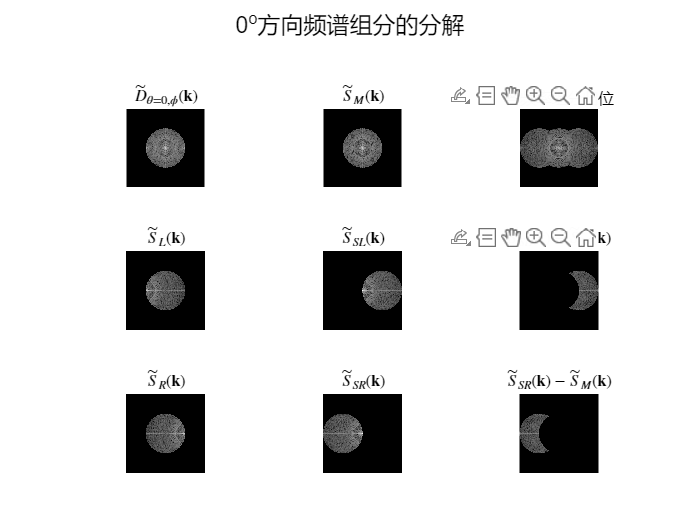

%0度频谱图合并
mask_0=zeros(305,305);
mask_0(S_M_0==0)=1;
S_S_L_0_rest=mask_0.*S_S_L_0;
subplot(3,3,6);imshow(log(abs(S_S_L_0_rest)+1)/10);
title(' $ \tilde{S}_{SL}({\mathbf {k}}) - \tilde{S}_{M}({\mathbf {k}})$', 'interpreter', 'latex');

S_S_R_0_rest=mask_0.*S_S_R_0;
subplot(3,3,9);imshow(log(abs(S_S_R_0_rest)+1)/10);
title(' $ \tilde{S}_{SR}({\mathbf {k}}) - \tilde{S}_{M}({\mathbf {k}})$', 'interpreter', 'latex');

S_0=S_S_R_0_rest+S_M_0+S_S_L_0_rest;
subplot(3,3,3);imshow(log(abs(S_0)+1)/10); title("各频率组分归位");

### 2. 60度方向

%分解出中间的频率成分
S_M_60=M_inv(1,1)*masked_S_0_60+M_inv(1,2)*masked_S_90_60+M_inv(1,3)*masked_S_180_60;
figure; subplot(3,3,1);imshow(log(abs(masked_S_0_60)+1)/10);title("60^oSII的频谱图");
subplot(3,3,2);imshow(log(abs(S_M_0)+1)/10)

%分解出左边的频率成分
S_L_60=M_inv(2,1)*masked_S_0_60+M_inv(2,2)*masked_S_90_60+M_inv(2,3)*masked_S_180_60;
subplot(3,3,4);imshow(log(abs(S_L_60)+1)/10)
%平移
[row_L_60,col_L_60]=Find_max_index(S_L_60)

row_L_60 = 219

col_L_60 = 115

S_S_L_60=[S_L_60(:,305-37:305),S_L_60(:,1:305-38)];
S_S_L_60=[S_S_L_60(67:305,:);S_S_L_60(1:66,:)];
subplot(3,3,5); imshow(log(abs(S_S_L_60)+1)/10);

%分解出右边的频率成分
S_R_60=M_inv(3,1)*masked_S_0_60+M_inv(3,2)*masked_S_90_60+M_inv(3,3)*masked_S_180_60;
subplot(3,3,7);imshow(log(abs(S_R_60)+1)/10);
%平移
S_S_R_60=[S_R_60(:,39:305),S_R_60(:,1:38)];
S_S_R_60=[S_S_R_60(305-65:305,:);S_S_R_60(1:305-66,:)];
subplot(3,3,8); imshow(log(abs(S_S_R_60)+1)/10);

### 60度频谱图合并

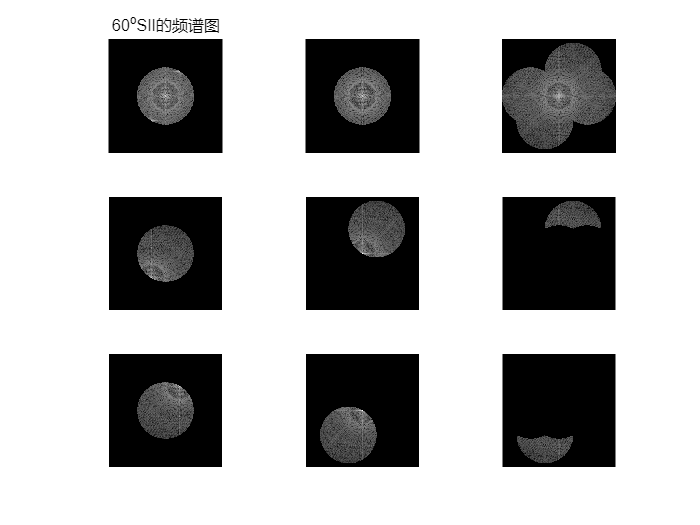

mask_60=zeros(305,305);
mask_60(S_0==0)=1;
S_S_L_60_rest=mask_60.*S_S_L_60;
subplot(3,3,6);imshow(log(abs(S_S_L_60_rest)+1)/10);

S_S_R_60_rest=mask_60.*S_S_R_60;
subplot(3,3,9);;imshow(log(abs(S_S_R_60_rest)+1)/10);

S_60=S_S_R_60_rest+S_0+S_S_L_60_rest;
subplot(3,3,3);;imshow(log(abs(S_60)+1)/10);

### 3. 120度方向

%分解出中间的频率成分
S_M_120=M_inv(1,1)*masked_S_0_120+M_inv(1,2)*masked_S_90_120+M_inv(1,3)*masked_S_180_120;
figure;subplot(3,3,1);imshow(log(abs(masked_S_0_120)+1)/10);title("120^oSII的频谱图");
subplot(3,3,2);imshow(log(abs(S_M_120)+1)/10)

%分解出左边的频率成分
S_L_120=M_inv(2,1)*masked_S_0_120+M_inv(2,2)*masked_S_90_120+M_inv(2,3)*masked_S_180_120;
subplot(3,3,4);imshow(log(abs(S_L_120)+1)/10)
%平移
[row_L_120,col_L_120]=Find_max_index(S_L_120)

row_L_120 = 219

col_L_120 = 191

S_S_L_120=[S_L_120(:,39:305),S_L_120(:,1:38)];
S_S_L_120=[S_S_L_120(67:305,:);S_S_L_120(1:66,:)];
subplot(3,3,5);imshow(log(abs(S_S_L_120)+1)/10);

%分解出右边的频率成分
S_R_120=M_inv(3,1)*masked_S_0_120+M_inv(3,2)*masked_S_90_120+M_inv(3,3)*masked_S_180_120;
subplot(3,3,7);imshow(log(abs(S_R_120)+1)/10)
%平移
S_S_R_120=[S_R_120(:,305-37:305),S_R_120(:,1:305-38)];
S_S_R_120=[S_S_R_120(305-65:305,:);S_S_R_120(1:305-66,:)];
subplot(3,3,8);imshow(log(abs(S_S_R_120)+1)/10);

### 120度频谱图合并

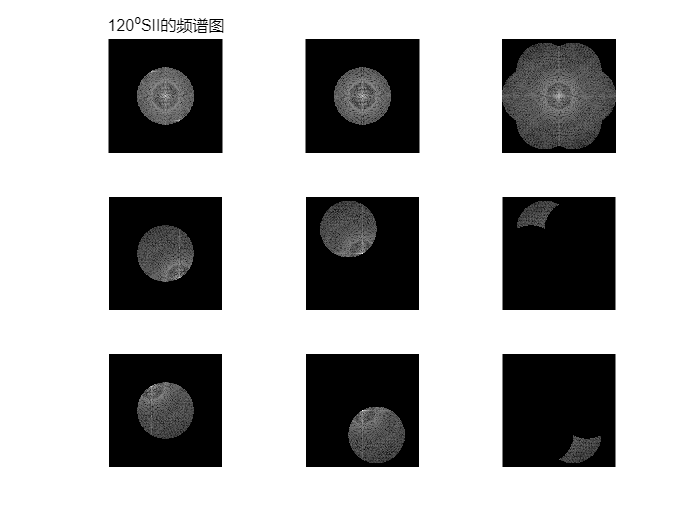

mask_120=zeros(305,305);
mask_120(S_60==0)=1;
S_S_L_120_rest=mask_120.*S_S_L_120;
subplot(3,3,6);imshow(log(abs(S_S_L_120_rest)+1)/10);

S_S_R_120_rest=mask_120.*S_S_R_120;
subplot(3,3,9);imshow(log(abs(S_S_R_120_rest)+1)/10);

S_120=S_S_R_120_rest+S_60+S_S_L_120_rest;
subplot(3,3,3);imshow(log(abs(S_120)+1)/10);

### 合并详解图

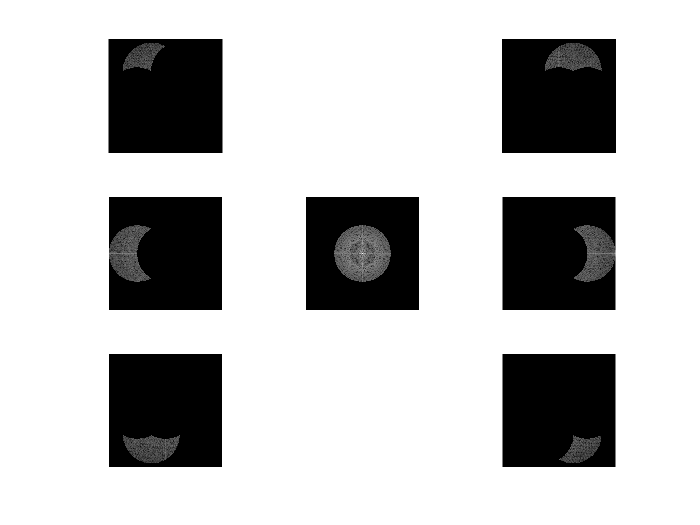

figure;
subplot(3,3,1);imshow(log(abs(S_S_L_120_rest)+1)/10);
subplot(3,3,3);imshow(log(abs(S_S_L_60_rest)+1)/10);
subplot(3,3,4);imshow(log(abs(S_S_R_0_rest)+1)/10);
subplot(3,3,5);imshow(log(abs(S_M_120)+1)/10);
subplot(3,3,6);imshow(log(abs(S_S_L_0_rest)+1)/10);
subplot(3,3,7);imshow(log(abs(S_S_R_60_rest)+1)/10);
subplot(3,3,9);imshow(log(abs(S_S_R_120_rest)+1)/10);

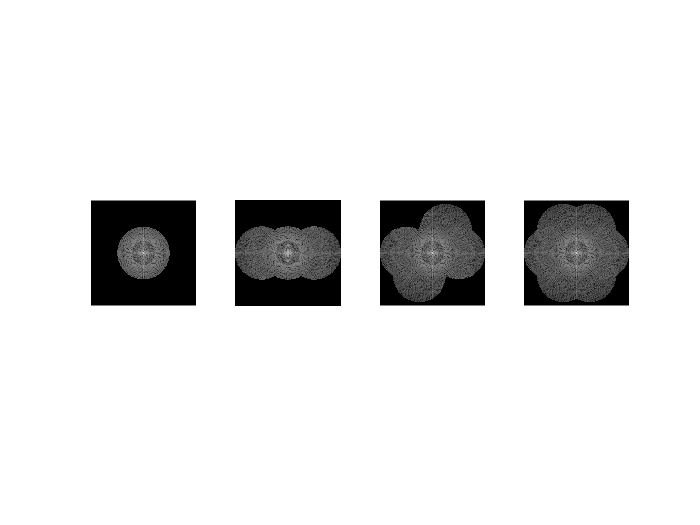


figure;
subplot(1,4,1);imshow(log(abs(S_M_120)+1)/10);
subplot(1,4,2);imshow(log(abs(S_0)+1)/10);
subplot(1,4,3);imshow(log(abs(S_60)+1)/10);
subplot(1,4,4);imshow(log(abs(S_120)+1)/10);

### 4. 傅里叶逆变换

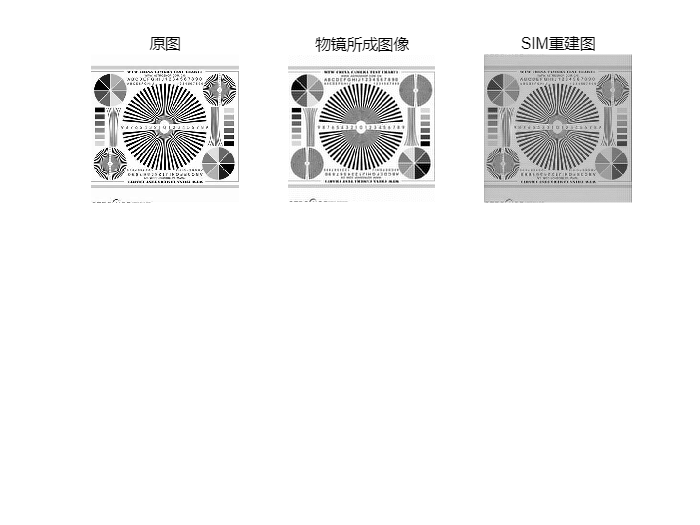

fr_120=real(ifft2(ifftshift(S_120)));  %频率域反变换到空间域，并取实部
ret_120=im2uint8(mat2gray(fr_120));    %更改图像类型
figure;%sgtitle('SIM重建算法效果展示');
subplot(2,3,1);
imshow(f);title("原图");
subplot(2,3,2);
imshow(lowpass_f);title("物镜所成图像");
subplot(2,3,3);
imshow(ret_120),title('SIM重建图');

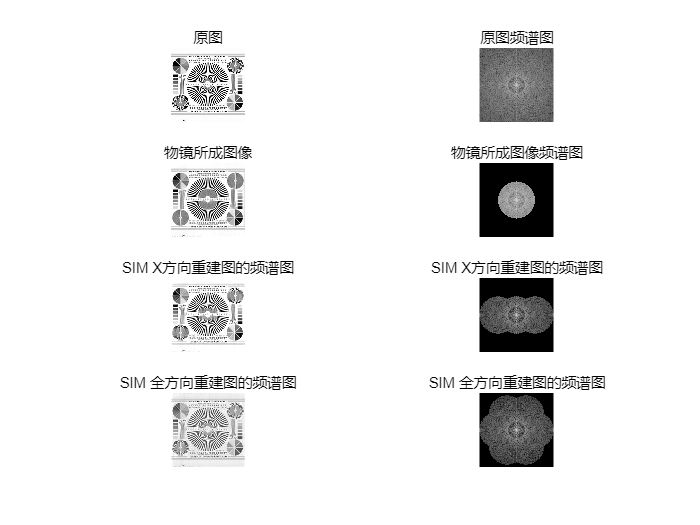

figure;%sgtitle('SIM重建算法效果展示');
subplot(4,2,1);imshow(f);title("原图");
subplot(4,2,2);imshow(S,[]);title("原图频谱图");

subplot(4,2,3);imshow(lowpass_f);title("物镜所成图像");
subplot(4,2,4);imshow(log(abs(masked_img)+1),[]);title("物镜所成图像频谱图");

subplot(4,2,5);imshow(log(abs(ifft2(ifftshift(S_0)))+1)*2.5),title('SIM X方向重建图的频谱图');
subplot(4,2,6);imshow(log(abs(S_0)+1)/10),title('SIM X方向重建图的频谱图');

subplot(4,2,7);imshow(ret_120*1.2),title('SIM 全方向重建图的频谱图');
subplot(4,2,8);imshow(log(abs(S_120)+1)/10),title('SIM 全方向重建图的频谱图');